**Daniel Park and Elias Wheatfall**

# **Gauntlet Challenge Quiver Plot and Calculating Distance**

**Warning: Before you run the code below, please **

## Quiver Plot

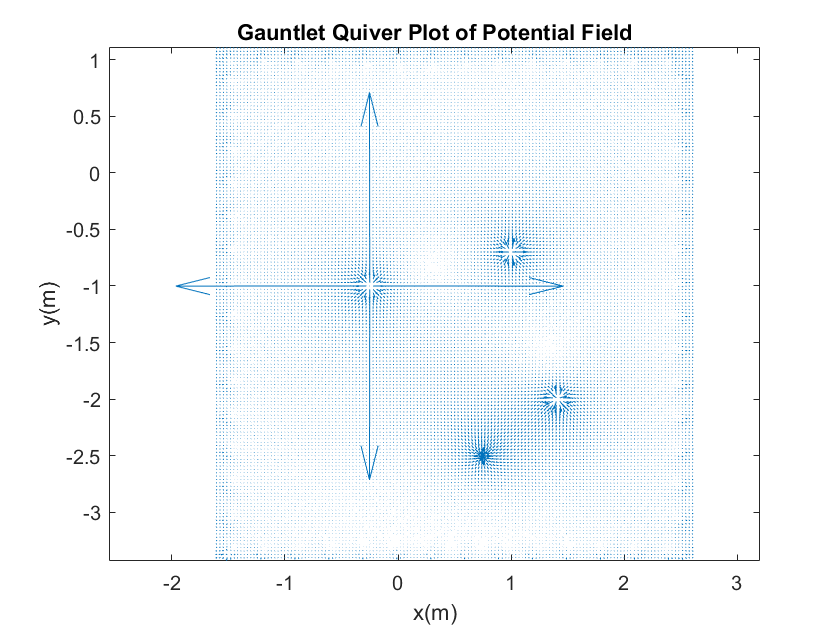

% Initialize all the scaling variables for the drive
syms x y
clf
scale = 5;
wall_scale = .5;
% Make the grid that the quiver plot will be on
[x,y] = meshgrid(-1.6:0.03:2.6,-3.4:0.03:1.1);

% Make the gradient equation for the obstacles and barrel of benevolence
eq = scale*-log(sqrt((x-1.41).^2 + (y+2).^2)) ...
    - scale*log(sqrt((x - 1).^2 + (y+.7).^2)) ...
    - scale*log(sqrt((x + .25).^2 + (y+1).^2)) ...
    + 6*log(sqrt((x -.75).^2 + (y+2.5).^2));

% Instance of the wall
wall = 0.3;

% x-axis walls on y = -1.5, 2.5
for a = -1.5:wall:2.5
    eq = eq - wall_scale*log(sqrt((x-a).^2 + (y+3.37).^2)) - wall_scale*log(sqrt((x-a).^2 + (y-1).^2));
end

% y-axis walls on y = -3.37, 1
for b = -3.37:wall:1
    eq = eq - wall_scale* log(sqrt((x+1.5).^2 + (y-b).^2)) - wall_scale*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% Plot the quiver diagram
[U,V] = gradient(eq);
h1 = quiver(x,y,-U,-V);
set(h1,'AutoScale','on', 'AutoScaleFactor', 40)
title("Gauntlet Quiver Plot of Potential Field")
xlabel("x(m)")
ylabel("y(m)")
axis equal

## Calculating Distance

%% Import the travel dataset csv file and put them in variables
gauntlet_travel = csvread('gauntlet_travel_dataset.csv',3);
% The elapsed time for each encoder value going up
timeseconds = gauntlet_travel((1:end),1);
% The left encoder values
encoderLeftmeters = gauntlet_travel((1:end),2);
% The right encoder values
encoderRightmeters = gauntlet_travel((1:end),3);

% Reinstate the time to start at 0
timeseconds = timeseconds - min(timeseconds);

% Calculate the left and right wheel velocities
left_wheel_vel = encoderLeftmeters./timeseconds;
right_wheel_vel = encoderRightmeters./timeseconds;

% Calculate the total Neato velocity
velocity = (left_wheel_vel + right_wheel_vel) ./ 2;

% Calculate the distance from the velocity and the elapsed time
distance = velocity.*timeseconds;

% Get the largest value in distance to show the total distance traveled by
% our Neato
total_measured_distance_traveled = max(distance)

total_measured_distance_traveled = 3.7957

% Calculate the optimal distance from the starting point of the Neato to
% the Barrel of Benevolence
positions = [0,0 ; 0.75,-2.5];
optimal_distance = pdist(positions,'euclidean')

optimal_distance = 2.6101